# Demonstrates the use of relational and logical operators

A = [5,0,-1; 3,10,2; 0,-4,8]

A =      5     0    -1
     3    10     2
     0    -4     8


Map = (A > 6) % 找尋矩陣中元素大於6值的行列位置

Map = 3×3 logical array
   0   0   0
   0   1   0
   0   0   1


location = find(Map) % 找尋矩陣中元素大於6的值

location =      5
     9


list = A(location)

list =     10
     8


list2 = A(find(A>6))

list2 =     10
     8


list3 = A(find(A>0 & A<=8 & A~=3))

list3 =      5
     2
     8


list4 = A(A>0 & A<=8 & A~=3)

list4 =      5
     2
     8


find(A)' % 找出矩陣X中的所有非零元素，並將這些元素的線性索引值(行優先尋找)

ans =      1     2     5     6     7     8     9


~A % 顯示各矩陣中元素是否為0元素

ans = 3×3 logical array
   0   1   0
   0   0   0
   1   0   0


~~A % 顯示各矩陣中元素是否為非0元素

ans = 3×3 logical array
   1   0   1
   1   1   1
   0   1   1


isequal(A, ~~A)

ans = logical
   0


# Demonstrates string manipulations.

a = 'Hello,';
b = 'world!';
c = [a, ' ', b];
disp(c)

Hello, world!


name = input('What is your name? ', 's'); % input 輸入轉字串
years = input('What is your age? ');
disp(['Hello, ', name, '! You are ', num2str(years), ' years old.'])

Hello, Eric! You are 66 years old.


str = sprintf('Pi = %.8f', pi);
disp(str)

Pi = 3.14159265


Names1 = [
    'David  '
    'John   '
    'Stephen'];
Names2 = char('David', 'John', 'Stephen');
if isequal(Names1, Names2)
    disp('The two lists are equal.')
end

The two lists are equal.


name = deblank(Names1(2,:));
disp(['The name ', name, ' has ', num2str(length(name)), ' characters.'])

The name John has 4 characters.


# Reads an expression from the keyboard, evaluates the expression, and outputs the resulting value.

disp('A Simple Calculator')

A Simple Calculator


while true
    expr = input('Enter an expression (or quit): ', 's'); %接收運算式
    if strcmp(expr, 'quit')
        break
    end
    disp([expr, ' = ', num2str(eval(expr))]) %字串轉數值計算
end

9*6 = 54


# Calculates three angles of a triangle, given the lengthes of three sides of the triangle, using the Law of Sines.

a = 5;
b = 6;
c = 7;
R = a*b*c/sqrt((a+b+c)*(a-b+c)*(b-c+a)*(c-a+b))

R =    3.572172541558801


alpha = asind(a/(2*R))

alpha =   44.415308597192976


beta = asind(b/(2*R))

beta =   57.121650435622520


gamma = asind(c/(2*R))

gamma =   78.463040967184497


sumAngle = alpha + beta + gamma

sumAngle =    180


A1 = a*b*c/(4*R)

A1 =   14.696938456699069


A2 = b*c*sind(alpha)/2

A2 =   14.696938456699069


# Calculates three angles of a triangle, given the lengthes of three sides of the triangle, using the Law of Cosines.

a = 5; b = 6; c = 7;
alpha = acosd((b^2+c^2-a^2)/(2*b*c))

alpha =   44.415308597192976


beta = acosd((c^2+a^2-b^2)/(2*c*a))

beta =   57.121650435622520


gamma = acosd((a^2+b^2-c^2)/(2*a*b))

gamma =   78.463040967184526


# Scalar Expressions

Calculates sin(π/ 4 ) using the Taylor series,

x = pi/4;
term1 = x;
term2 = -x^3/(3*2);
term3 = x^5/(5*4*3*2);
term4 = -x^7/(7*6*5*4*3*2);
format long
sinx =term1 + term2 + term3 + term4

sinx =    0.707106469575178


exact = sin(x)

exact =    0.707106781186547


error = (sinx-exact)/exact

error =     -4.406850247592559e-07


# Use of For-Loop

Calculates sin(π 4 ) using the Taylor series, sin x = (?1)k?1 * (x^2k?1/ ((2k ?1)!))

x = pi/4; n = 4; sinx = 0;
for k = 1:n
    sinx = sinx + ((-1)^(k-1))*(x^(2*k-1))/factorial(2*k-1);
end
format long
sinx

sinx =    0.707106469575178


exact = sin(x)

exact =    0.707106781186547


error = (sinx-exact)/exact

error =     -4.406850247592559e-07


# Vector Expressions

Calculates sin(π 4 ) using the Taylor series

x = pi/4; n = 4; k = 1:n;
format long
sinx = sum(((-1).^(k-1)) .* (x .^ (2*k-1)) ./ factorial(2*k-1))

sinx =    0.707106469575178


exact = sin(x)

exact =    0.707106781186547


error = (sinx-exact)/exact

error =     -4.406850247592559e-07


# Matrix Expressions Plots a sin(x)-versus-x curve using the Taylor series,

x = linspace(0,pi/2,20);
n = 4;
k = 1:n

k =      1     2     3     4


[X, K] = meshgrid(x, k) % 建立 X與 K矩陣，建立三維網格矩陣

X =                    0   0.082673490883942   0.165346981767884   0.248020472651826   0.330693963535768   0.413367454419710   0.496040945303652   0.578714436187593   0.661387927071535   0.744061417955477   0.826734908839419   0.909408399723361   0.992081890607303   1.074755381491245   1.157428872375187   1.240102363259129   1.322775854143071   1.405449345027013   1.488122835910955   1.570796326794897
                   0   0.082673490883942   0.165346981767884   0.248020472651826   0.330693963535768   0.413367454419710   0.496040945303652   0.578714436187593   0.661387927071535   0.744061417955477   0.826734908839419   0.909408399723361   0.992081890607303   1.074755381491245   1.157428872375187   1.240102363259129   1.322775854143071   1.405449345027013   1.488122835910955   1.570796326794897
                   0   0.082673490883942   0.165346981767884   0.248020472651826   0.330693963535768   0.413367454419710   0.496040945303652   0.578714436187593   0.661387927071535   0.744061417

K =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4


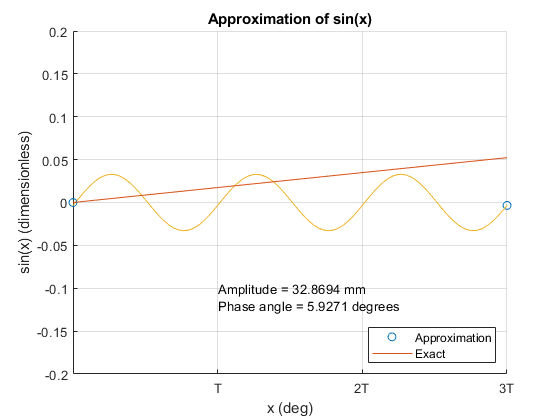

sinx = sum(((-1).^(K-1)).*(X .^ (2*K-1))./factorial(2*K-1));
plot(x*180/pi, sinx, 'o', x*180/pi, sin(x))
title('Approximation of sin(x)')
xlabel('x (deg)')
ylabel('sin(x) (dimensionless)')
legend('Approximation', 'Exact', 'Location', 'southeast')

# Multiple Curves Plots sin(x)-versus-x curves using 1-, 2-, 3-, and 4-item Taylor series

x = linspace(0,pi/2,20);
n = 4;
k = (1:n);
[X, K] = meshgrid(x, k);
sinx = cumsum(((-1).^(K-1)).*(X .^ (2*K-1))./factorial(2*K-1))

sinx =                    0   0.082673490883942   0.165346981767884   0.248020472651826   0.330693963535768   0.413367454419710   0.496040945303652   0.578714436187593   0.661387927071535   0.744061417955477   0.826734908839419   0.909408399723361   0.992081890607303   1.074755381491245   1.157428872375187   1.240102363259129   1.322775854143071   1.405449345027013   1.488122835910955   1.570796326794897
                   0   0.082579313292820   0.164593561038907   0.245477677691530   0.324666597703956   0.401595255529451   0.475698585621285   0.546411522432725   0.613169000417038   0.675405954027492   0.732557317717354   0.784058025939892   0.829343013148374   0.867847213796068   0.899005562336240   0.922252993222158   0.937024440907091   0.942754839844306   0.938879124487070   0.924832229288650
                   0   0.082579345477569   0.164594590950894   0.245485498585678   0.324699554887524   0.401695832871884   0.475948854234007   0.546952451518888   0.614223630291221   0.677306

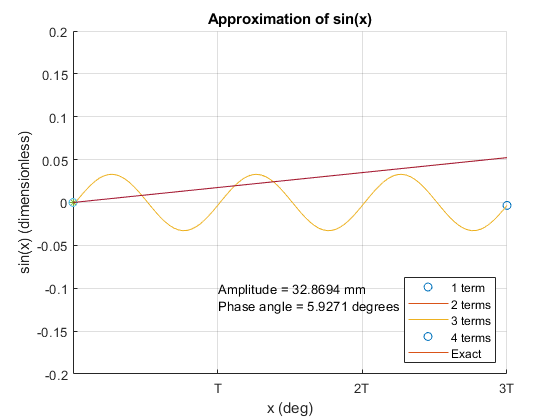

plot(x*180/pi, sinx(1,:), '+-', ...
     x*180/pi, sinx(2,:), 'x-', ...
     x*180/pi, sinx(3,:), '*', ...
     x*180/pi, sinx(4,:), 'o', ...
     x*180/pi, sin(x))
title('Approximation of sin(x)')
xlabel('x (deg)')
ylabel('sin(x) (dimensionless)')
legend('1 term', '2 terms', '3 terms', '4 terms', 'Exact', ...
       'Location', 'southeast')

# Plots a φ (x, y) -versus-(x,y) surface, where φ (x, y) is the solution of the Laplace equation:

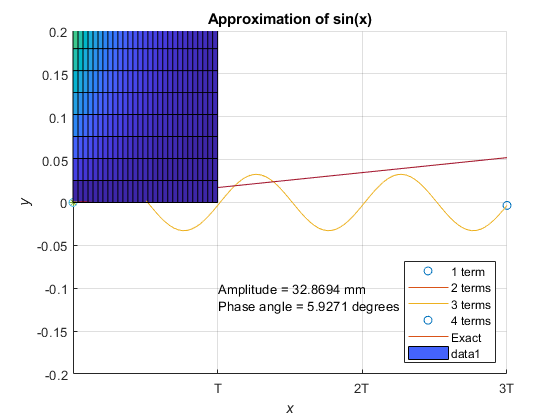

k = 1:20;
x = linspace(0,1,30);
y = linspace(0,1,40);
[X,Y,K]  = meshgrid(x, y, k);
Phi = sum(4*(1-cos(K*pi))./(K*pi).^3.*exp(-K.*X*pi).*sin(K.*Y*pi), 3);
surf(x, y, Phi)
xlabel('\itx')
ylabel('\ity')
zlabel('\phi(\itx\rm,\ity\rm)')

# Calculates the deflection of a simply supported beam subject to a vertical force at quarter point.

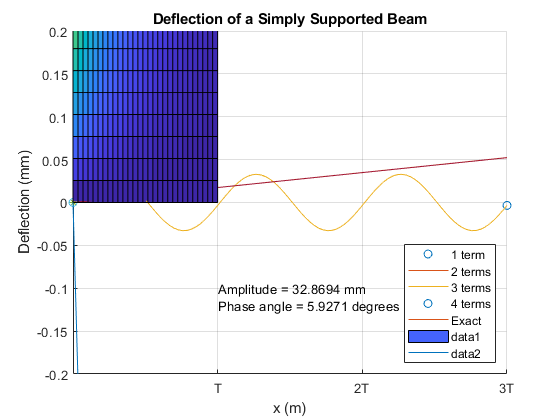

w = 0.1;
h = 0.1;
L = 8;
E = 210e9;
F = 3000;
a = L/4;
I = w*h^3/12;
R = F/L*(L-a);
theta = F*a/(6*E*I*L)*(2*L-a)*(L-a);
x = linspace(0,L,100);
y = -theta*x+R*x.^3/(6*E*I)-F/(6*E*I)*((x>a).*((x-a).^3));
plot(x,y*1000)
title('Deflection of a Simply Supported Beam')
xlabel('x (m)'); ylabel('Deflection (mm)')

y = -y;
[ymax, index] = max(y)

ymax =    0.012776797961983


index =     45


fprintf('Maximum deflection %.2f mm at x = %.2f m\n', ymax*1000, x(index))

Maximum deflection 12.78 mm at x = 3.56 m


# Plots a displacement-versustime curve for an undamped free vibrations of a supported machine.

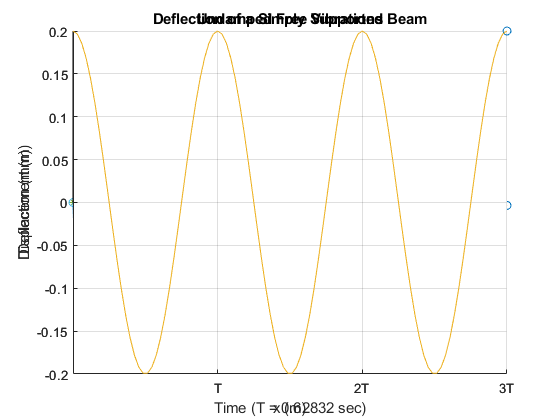

m = 1; k = 100; delta = 0.2;
omega = sqrt(k/m);
T = 2*pi/omega;
t = linspace(0, 3*T, 100);
x = delta*cos(omega*t);
axes('XTick', T:T:3*T, 'XTickLabel', {'T','2T','3T'});
axis([0, 3*T, -0.2, 0.2]) % axis([x_str, x_end, y_str, y_end])
grid on
hold on
comet(t, x)
title('Undamped Free Vibrations')
xlabel(['Time (T = ', num2str(T), ' sec)'])
ylabel('Displacement (m)')

# Plots a displacement-versustime curve for a damped free vibrations of a supported machine.

m = 1; k = 100; c = 1; delta = 0.2;
omega = sqrt(k/m);
cC = 2*m*omega;
omegaD = omega*sqrt(1-(c/cC)^2);
T = 2*pi/omegaD;
t = linspace(0, 3*T, 100);
x = delta*exp(-c*t/(2*m)).*(cos(omegaD*t)+c/(2*m*omegaD)*sin(omegaD*t));
axes('XTick', T:T:3*T, 'XTickLabel', {'T','2T','3T'});
axis([0, 3*T, -0.2, 0.2])
grid on
hold on
comet(t, x)
title('Damped Free Vibrations')
xlabel(['Time (T = ', num2str(T), ' sec)'])
ylabel('Displacement (m)')

# Plots a steady-state displacement-versus-time curve for a damped harmonically forced vibrations of a supported machine.

System parameters

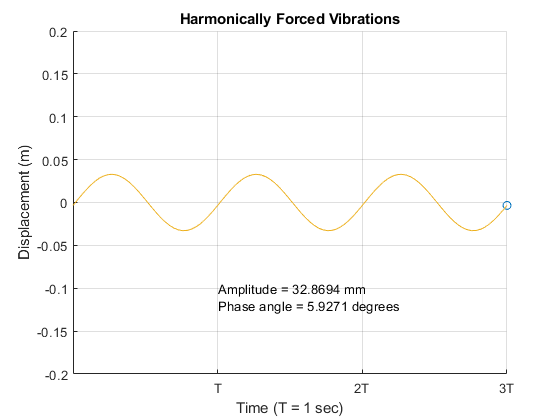

m = 1; k = 100; c = 1;
f = 2; omegaF = 2*pi;

% System Response
omega = sqrt(k/m);
cC = 2*m*omega;
rC = c/cC;
rW = omegaF/omega;
xm = (f/k)/sqrt((1-rW^2)^2+(2*rC*rW)^2);
phi = atan((2*rC*rW)/(1-rW^2));
T = 2*pi/omegaF;
t = linspace(0, 3*T, 100);
x = xm*sin(omegaF*t-phi);

% Graphic output
axes('XTick', T:T:3*T, 'XTickLabel', {'T','2T','3T'});
axis([0, 3*T, -0.2, 0.2])
grid on
hold on
title('Harmonically Forced Vibrations')
xlabel(['Time (T = ', num2str(T), ' sec)'])
ylabel('Displacement (m)')
text(T,-0.1,['Amplitude = ', num2str(xm*1000), ' mm']) % text(pos_x,pos_y,[str])
text(T,-0.12,['Phase angle = ', num2str(phi*180/pi), ' degrees'])
comet(t, x)